# Time series analysis: Wavelet transforms and Phase coupling

Part2 - Wavelet transforms

*Description of the objectives*

*As usual, we first load and preprocess the behavioral and spiking data*

loadparams = DefineLoadParams;
Nav = LoaddataNav(loadparams);
Spk = LoaddataSpk(loadparams, Nav.sampleTimes);

*But now we will also load the Lfp data. You can call LoaddataLfp to do so.*

Lfp = LoaddataLfp(loadparams, Nav.sampleTimes);

*Defining a set of parameters needed before we compute the wavelet transforms.*

%Experimental condition over which time frequency analyses will be
%conducted
TFparams.condition = [1 3 5];

%directions along X over which time frequency analyses will be conducted
TFparams.dir = [-1 1];

%Minimum speed threshold over which time frequency analyses will be 
%conducted
TFparams.spdthreshold = 2.5;

%Frequency range for TF analysis
TFparams.freqrange = [1 200];

%Sampling rate of the raw lfps
TFparams.sampleRate_raw = 1 / nanmean(diff(Lfp.sampleTimes_raw));

%Sampling rate of theta
TFparams.sampleRate_theta = 1 / nanmean(diff(Lfp.sampleTimes_theta));

Plot the 1D wavelet transform of the hippocampal Lfp for the first 2 seconds of the pre-run condition.

%Time when pre-run starts
timestart = Nav.sampleTimes(find(Nav.Condition == 1, 1, 'first'));

%Lfp indices of the first 2 seconds
tidx = find(Lfp.sampleTimes_raw >= timestart & Lfp.sampleTimes_raw <= timestart + 2);

%Sampling frequency of raw Lfp signals
rawFs = 1 / mean(diff(Lfp.sampleTimes_raw));

%Run the wavelet transform calculation using the cwt function of the
%wavelet toolbox, with a Morse wavelet family with the default parameters.
[wt,f,~,~] = cwt(Lfp.LfpHpc_raw(tidx),'morse', rawFs);

%The output of cwt is complex numbers. We take the modulus of it, which
%represent the power
wt = abs(wt);

%Plotting the wavelet transform
figure;
imagesc(Lfp.sampleTimes_raw(tidx), f, wt);

%Scaling the Y axis correctly (be careful, the range of frequencies is
%on a log space and imagesc doesn't know about it
set(gca, 'Yscale', 'log', 'Ydir', 'normal', 'YTick', [5 10 20 40 80 160], 'Ylim', [min(f) max(f)]);

%Colorbar, labels, title
c = colorbar;
c.Label.String = 'Magnitude';
xlabel('Time (s)')
ylabel('Frequency (Hz)');
title('Wavelet transform of hippocampal Lfp')

We would like to compute the variations of these oscillations across positions of the animal on the track.

Let's first select the time indices over which we want to map the spatial profile of the oscillations.

%Time indices over which some TF analysis will be performed
tidx = ismember(Nav.Condition, TFparams.condition) &...
       ismember(Nav.XDir, TFparams.dir) &...
       Nav.Spd > TFparams.spdthreshold &...
       ~isnan(Nav.Xpos);
        
%Sampling frequency of raw Lfp signals
rawFs = 1 / mean(diff(Lfp.sampleTimes_raw));

%Sampling frequency of behavioral data
navFs = 1 / mean(diff(Nav.sampleTimes));

Although we could first start with by applying the wavelet transform to our entire signal before computing the spatial profile, this wouldn't be very effeicient: first it would take a lot of time and memory to do so over more than 6 hrs of recording sampled at 600Hz; and the time spent by the animal on the track is only a fraction of this recording so we don't need to do the wavelet transform over all of it.

However, we do need some continuous chunks of data of reasonable length to get a good approximation over low frequencies. So, before running the wavelet transform, we have to find thos continuous period and select time bins in the wavelet transform afterwards.

%Finding segments of data that are less than 300 seconds apart and merge
%them
brkwin = 2 * floor(300 * navFs /2) + 1;
tidxmerge = smooth(double(tidx), brkwin, 'moving') > 0;

startidx = find(diff(tidxmerge(brkwin:end)) > 0) + floor(brkwin/2);
endidx = find(diff(tidxmerge(1:end - brkwin + 1)) < 0) - floor(brkwin/2);
if startidx(1) > endidx(1) %if conditions were fulfilled when recoding started
    startidx = [1 ; startidx];
end
if startidx(end) > endidx(end) %if conditions were fulfilled when recoding stopped
    endidx = [endidx ; numel(Nav.sampleTimes)];
end

%Converting the indices from behavioral indices to raw Lfp indices
startidx_lfp = floor((startidx - 1) / navFs * rawFs + 1);
endidx_lfp = floor((endidx - 1) / navFs * rawFs + 1);

%Number of data segments
nseg = numel(startidx_lfp);

%Duration of segments
segduration = (endidx_lfp - startidx_lfp) / rawFs;

Now that we have the necessary segments, we can run the wavelet transform on each segment. But one more thing: we will also resample the returned wavelet transforms in the frequency domain (because they may not have the frequencies) and in the time domain (because we don't need 600 Hz resolution once the power of the oscillation is calculated).

%List of frequencies to resample the wavelet transform
fq_new = logspace(log10(TFparams.freqrange(1)),log10(TFparams.freqrange(2)),96);

%Initializing the final array of time x frequency wavelet transform,
%sampled according to Nav.sampleTimes.
wthpc = NaN(numel(Nav.sampleTimes), numel(fq_new));

%Calculating the wavelet transform over the identified segments of data
for k = 1:nseg
    %wavelet transform with Morse wavelet
    [wt,f,~,~] = cwt(Lfp.LfpHpc_raw(startidx_lfp(k):endidx_lfp(k)),'morse',rawFs, 'FrequencyLimits', [fq_new(1) fq_new(end)]);
    
    %cwt returns frequencies from high to low. Flipping it up/down to avoid
    %confusions later.
    wt = flipud(wt);
    f = flipud(f);

    %Power of oscillations
    wt = abs(wt);
    
    %Time along the first dimension.
    wt = wt';

    %Saving wavelet transform into wtresp at the resolution
    t_old = Lfp.sampleTimes_raw(startidx_lfp(k):endidx_lfp(k));
    t_new = Nav.sampleTimes(startidx(k):endidx(k));
    wthpc(startidx(k):endidx(k),:) = interp2(f, t_old, wt, fq_new, t_new);
end

Plot the same first 10 seconds as before and check that everything is correct

%Time when pre-run starts
timestart = Nav.sampleTimes(find(Nav.Condition == 1, 1, 'first'));

%Lfp indices of the first 10 seconds
tidx = find(Nav.sampleTimes >= timestart & Nav.sampleTimes <= timestart + 2);


%Plotting the wavelet transform
figure;
imagesc(Nav.sampleTimes(tidx), f, wthpc(tidx,:)');

%Correct scaling of the Y axis
set(gca, 'Yscale', 'log', 'Ydir', 'normal', 'YTick', [5 10 20 40 80 160], 'Ylim', [min(f) max(f)]);

%Colorbar, labels, title
c = colorbar;
c.Label.String = 'Magnitude';
xlabel('Time (s)')
ylabel('Frequency (Hz)');
title('Wavelet transform of hippocampal Lfp')

Now we are ready to compute the spatial profile of the power at each freqquency. We could do it all over from scratch or we can directly use MapsAnalyses2D.m, after some adjustment of the parameters.

%Getting default parameters to compute spatial profiles
TFparams.mapsparams = DefineMapsParams(Nav,Spk);

%Replacing values for time indices selection.
TFparams.mapsparams.condition = TFparams.condition;
TFparams.mapsparams.dir = TFparams.dir;
TFparams.mapsparams.spdthreshold = TFparams.spdthreshold;

%Replacing values related to subsetting and scaling the response
%variable
TFparams.mapsparams.cellidx = true(1, size(wthpc, 2));
TFparams.mapsparams.nspk_th = -inf;
TFparams.mapsparams.scalingFactor = 1;

%Running place field analysis on the wavelet transform
tfMaps = MapsAnalyses2D(Nav,wthpc,TFparams.mapsparams);

*Plot the spatial profile of all fequencies, for both direction of travel. To your opitnion, are there frequencies tuned to positions?*

figure;

%Titles for directions
dirnames = {'Right to Left','Left to Right'};

%Plotting
for idir = 1:2
    subplot(2,1,idir);
    imagesc(tfMaps.Xbincenters,fq_new,tfMaps.mapXY(:,:,idir));
    set(gca, 'Ylim', [fq_new(1) fq_new(end)], 'Ydir', 'normal');
    set(gca, 'Yscale', 'log', 'Ytick',[5 10 20 40 80 160]);
    title(dirnames{idir});

end

%Title, label, etc
subplot(2,1,2);
c = colorbar;
c.Label.String = 'Magnitude';
xlabel('Position (%)');
ylabel('Frequency (Hz)');

subplot(2,1,1);
colorbar('Visible','off');

The recording also contains Lfp signals recorded in the baso-lateral amygdala (bla).

Compute and plot the wavelet coherence between bla and hpc Lfps over the first two seconds of the pre-run condition. You can use the function cwt from the wavelet toolbox.

%Time when pre-run starts
timestart = Nav.sampleTimes(find(Nav.Condition == 1, 1, 'first'));

%Lfp indices of the first 2 seconds
tidx = find(Lfp.sampleTimes_raw >= timestart & Lfp.sampleTimes_raw <= timestart + 2);

%Sampling frequency of raw Lfp signals
rawFs = 1 / mean(diff(Lfp.sampleTimes_raw));

%Run the wavelet coherence calculation using the wcoherence from the
%wavelet toolbox, using the default parameters.
[wc,~,f] = wcoherence(Lfp.LfpHpc_raw(startidx_lfp(k):endidx_lfp(k)),Lfp.LfpBla_raw(startidx_lfp(k):endidx_lfp(k)),rawFs ...
                      , 'FrequencyLimits', [1 100]);

%The output of cwt is complex numbers. We take the modulus of it, which
%represent the power
wc = abs(wc);

%Plotting the wavelet transform
figure;
imagesc(Lfp.sampleTimes_raw(tidx), f, wc);

%Scaling the Y axis correctly (be careful, the range of frequencies is
%on a log space and imagesc doesn't know about it
set(gca, 'Yscale', 'log', 'Ydir', 'normal', 'YTick', [5 10 20 40 80 160], 'Ylim', [min(f) max(f)]);

%Colorbar, labels, title
c = colorbar;
c.Label.String = 'Magnitude squared coherence';
xlabel('Time (s)')
ylabel('Frequency (Hz)');
title('Wavelet coherence between hippocampal and bla Lfps')

Do the same as position profile analsys as with the wavelet transform, but using now the coherence between hpc and bla.

%List of frequencies to resample the wavelet coherence
fq_new = logspace(log10(TFparams.freqrange(1)),log10(TFparams.freqrange(2)),96);

%Initializing the final array of time x xfrequency wavelet transform
wcoh = NaN(numel(Nav.sampleTimes), numel(fq_new));

%Calculating the wavelet coherence over the identified segments of data
for k = 1:nseg
    %wavelet coherence with Morlet wavelet
    [wc,~,f] = wcoherence(Lfp.LfpHpc_raw(startidx_lfp(k):endidx_lfp(k)),Lfp.LfpBla_raw(startidx_lfp(k):endidx_lfp(k)),rawFs, 'FrequencyLimits', [fq_new(1) fq_new(end)]);
    
    %wcoherence returns frequencies from high to low. Flipping it up/down to avoid
    %confusions later.
    wc = flipud(wc);
    f = flipud(f);

    %Power of oscillations
    wc = abs(wc);
    
    %Time along the first dimension.
    wc = wc';

    %flipping

    %Saving wavelet transform into wtresp at the resolution
    t_old = Lfp.sampleTimes_raw(startidx_lfp(k):endidx_lfp(k));
    t_new = Nav.sampleTimes(startidx(k):endidx(k));
    wcoh(startidx(k):endidx(k),:) = interp2(f, t_old, wc, fq_new, t_new);
end

%Compute the spatial profile of power across frequenciesby calling
%MapsAnalyses2D.

%Getting default parameters to compute spatial profiles
TFparams.mapsparams = DefineMapsParams(Nav,Spk);

%Replacing values for time indices selection.
TFparams.mapsparams.condition = TFparams.condition;
TFparams.mapsparams.dir = TFparams.dir;
TFparams.mapsparams.spdthreshold = TFparams.spdthreshold;

%Replacing values related to subsetting and scaling the response
%variable
TFparams.mapsparams.cellidx = true(1, size(wcoh, 2));
TFparams.mapsparams.nspk_th = -inf;
TFparams.mapsparams.scalingFactor = 1;

%Running place field analysis on wavelet coherence
cohMaps = MapsAnalyses2D(Nav,wcoh,TFparams.mapsparams);

*Plot the spatial profile of the Hpc-bla coherence, for both direction of travel.*

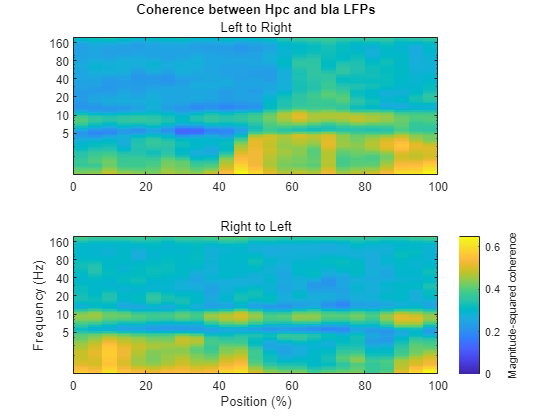

figure;

%Titles for directions
dirnames = {'Right to Left','Left to Right'};

%Plotting
for idir = 1:2
    subplot(2,1,idir);
    imagesc(cohMaps.Xbincenters,fq_new,cohMaps.mapXY(:,:,idir));
    set(gca, 'Ylim', [fq_new(1) fq_new(end)], 'Ydir', 'normal');
    set(gca, 'Yscale', 'log', 'Ytick',[5 10 20 40 80 160]);
    subtitle(dirnames{idir});

end

%Title, label, etc
subplot(2,1,2);
c = colorbar;
c.Label.String = 'Magnitude-squared coherence';
xlabel('Position (%)');
ylabel('Frequency (Hz)');

subplot(2,1,1);
colorbar('Visible','off');
title('Coherence between Hpc and bla LFPs')